# **Lab1- Recapitulare TSA la ctrb, obsv, stabilizabilitate si detectabilitate. PBH**

clear
close all
clc

A = [19 9 -9 -16;
     7 1 -7 2;
     16 0 -6 -14;
     8 8 -8 -6];

B = [5;
     3;
     2;
     3];

C = [-1 0 2 2];

D = 5;

Pc = ctrb(A,B)

Pc =            5          56         620        6800
           3          30         300        3000
           2          26         320        3800
           3          30         300        3000



Po = obsv(A,C)

Po =           -1           0           2           2
          29           7         -19         -24
         104          76          -4         -40
        2124         692       -1124       -1216



disp('Rangul matricii de ctrb Pc');

Rangul matricii de ctrb Pc


disp(rank(Pc));

     2




disp('Rangul matricii de obsv Po');

Rangul matricii de obsv Po


disp(rank(Po));

     4




disp('Valorile si vectorii proprii ale lui A');

Valorile si vectorii proprii ale lui A


[V_eig,Lam] = eig(A)

V_eig =    0.0000 + 0.0000i   0.0000 - 0.0000i  -0.7071 + 0.0000i   0.7071 + 0.0000i
   0.7071 - 0.0000i   0.7071 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i
   0.7071 + 0.0000i   0.7071 + 0.0000i  -0.7071 + 0.0000i   0.7071 + 0.0000i
   0.0000 + 0.0000i   0.0000 - 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i


Lam =   -6.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i  -6.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i  10.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  10.0000 + 0.0000i



disp('Este 10 controlabil?');

Este 10 controlabil?


[10*eye(4) - A B]

ans =     -9    -9     9    16     5
    -7     9     7    -2     3
   -16     0    16    14     2
    -8    -8     8    16     3


disp(rank([10*eye(4) - A B]));

     4




disp('Este -6 controlabil?');

Este -6 controlabil?


[-6*eye(4) - A B]

ans =    -25    -9     9    16     5
    -7    -7     7    -2     3
   -16     0     0    14     2
    -8    -8     8     0     3


disp(rank([-6*eye(4) - A B]));

     3




sys = ss(A,B,C,D)


sys =
 
  A = 
        x1   x2   x3   x4
   x1   19    9   -9  -16
   x2    7    1   -7    2
   x3   16    0   -6  -14
   x4    8    8   -8   -6
 
  B = 
       u1
   x1   5
   x2   3
   x3   2
   x4   3
 
  C = 
       x1  x2  x3  x4
   y1  -1   0   2   2
 
  D = 
       u1
   y1   5
 
Continuous-time state-space model.



poles = [-1 -1 -3 -4];

[U,E,V] = svd(Pc)

U =    -0.7666    0.1113    0.6324    0.0092
   -0.3385   -0.5343   -0.3059   -0.7116
   -0.4281    0.6455   -0.6324   -0.0092
   -0.3385   -0.5343   -0.3265    0.7024


E = 1.0e+03 *

    8.9079         0         0         0
         0    0.0461         0         0
         0         0    0.0000         0
         0         0         0    0.0000


V =    -0.0008   -0.0295    0.0258    0.9992
   -0.0083   -0.1961   -0.9804    0.0195
   -0.0915   -0.9759    0.1953   -0.0339
   -0.9958    0.0914   -0.0098    0.0022


Rr = orth(Pc)

Rr =    -0.7666    0.1113
   -0.3385   -0.5343
   -0.4281    0.6455
   -0.3385   -0.5343



Pc_ctrb = Pc(:, 1:2)

Pc_ctrb =      5    56
     3    30
     2    26
     3    30



Tinv = U

Tinv =    -0.7666    0.1113    0.6324    0.0092
   -0.3385   -0.5343   -0.3059   -0.7116
   -0.4281    0.6455   -0.6324   -0.0092
   -0.3385   -0.5343   -0.3265    0.7024



A1 = eye(4) / Tinv * A * Tinv

A1 =    10.8087    1.2765  -29.3122   20.4746
   -0.5123    9.1913    4.8147   -3.3767
    0.0000   -0.0000   -4.4876   -1.9685
    0.0000   -0.0000    1.1620   -7.5124


B1 = eye(4) / Tinv * B

B1 =    -6.7198
   -1.3581
    0.0000
         0


C1 = C * Tinv

C1 =    -0.7666    0.1113   -2.5502    1.3771


D1 = D

D1 = 5


Pc_transformed = ctrb(A1(1:2,1:2), B1(1:2))

Pc_transformed =    -6.7198  -74.3659
   -1.3581   -9.0399


Po_transformed = obsv(A1(1:2,1:2), C1(:,1:2))

Po_transformed =    -0.7666    0.1113
   -8.3425    0.0443



disp(rank(Pc_transformed));

     2



disp(rank(Po_transformed));

     2



Ca scmecherie: Eu nu am cum sa fac acker pe sistem nectrb. Practic ce fac este sa asocies priva valoare proprie din A cu primul pol etc sI fac

 -acker(A1_1,B1_1,polii care au asociat valoare proprie ctrb)

f = -acker(A1(1:2,1:2), B1(1:2),[-3 -4])

f =     9.1872  -25.5773



f1_1 = -acker(A1(1:2,1:2), B1(1:2),[-3 -3])

f1_1 =     8.6358  -23.5850



f2_1 = -acker(A1(1:2,1:2), B1(1:2),[-3 -40])

f2_1 =    29.0400  -97.3009




P = ss(A1(1:2,1:2)+B1(1:2)*f, B1(1:2), C1(:,1:2),D1)


P =
 
  A = 
           x1      x2
   x1  -50.93   173.2
   x2  -12.99   43.93
 
  B = 
           u1
   x1   -6.72
   x2  -1.358
 
  C = 
            x1       x2
   y1  -0.7666   0.1113
 
  D = 
       u1
   y1   5
 
Continuous-time state-space model.


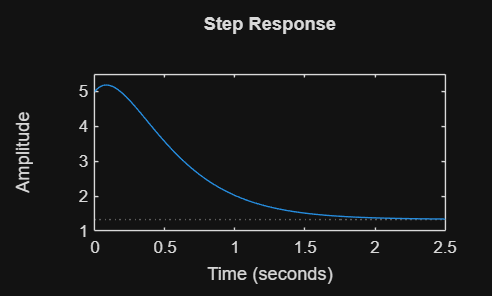


figure
step(P);



P1 = ss(A1(1:2,1:2)+B1(1:2)*f1_1, B1(1:2), C1(:,1:2),D1)


P1 =
 
  A = 
           x1      x2
   x1  -47.22   159.8
   x2  -12.24   41.22
 
  B = 
           u1
   x1   -6.72
   x2  -1.358
 
  C = 
            x1       x2
   y1  -0.7666   0.1113
 
  D = 
       u1
   y1   5
 
Continuous-time state-space model.


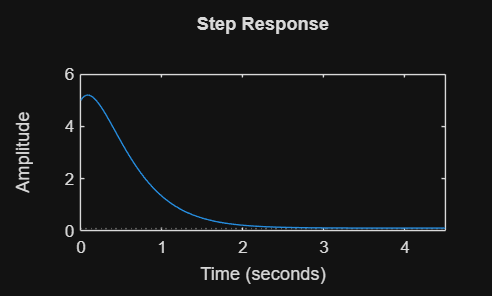


figure
step(P1);


P2 = ss(A1(1:2,1:2)+B1(1:2)*f2_1, B1(1:2), C1(:,1:2),D1)


P2 =
 
  A = 
           x1      x2
   x1  -184.3   655.1
   x2  -39.95   141.3
 
  B = 
           u1
   x1   -6.72
   x2  -1.358
 
  C = 
            x1       x2
   y1  -0.7666   0.1113
 
  D = 
       u1
   y1   5
 
Continuous-time state-space model.


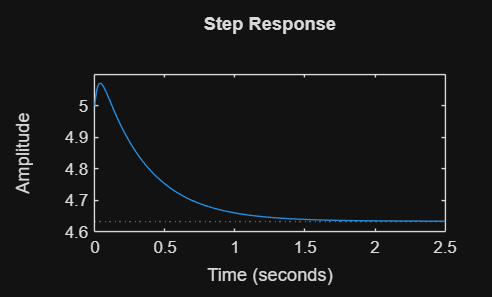


figure
step(P2);

## Lab1 BdC

#### damp(sys) afla frecvent,a naturala si coeficientul de amortizare

clear
close all
clc

load("E:\Radu editing document\SS + TCAI + TSA\CO + RSA\CO+RSA\CO+RSA\CO\RCAM.mat")

disp('valorile proprii ale lui A_lat');

valorile proprii ale lui A_lat


[V_lat, Lamlat] = eig(A_lat)

V_lat =   -0.7984 + 0.0000i  -0.0171 + 0.0072i  -0.0171 - 0.0072i   0.0160 + 0.0000i  -0.0000 + 0.0000i
   0.0508 + 0.0000i   0.0028 - 0.0047i   0.0028 + 0.0047i  -0.0106 + 0.0000i   0.0000 + 0.0000i
   0.5975 + 0.0000i   0.0201 + 0.0205i   0.0201 - 0.0205i  -0.0895 + 0.0000i   0.0000 + 0.0000i
  -0.0381 + 0.0000i  -0.0085 - 0.0014i  -0.0085 + 0.0014i   0.0601 + 0.0000i  -1.0000 + 0.0000i
   0.0385 + 0.0000i   0.9994 + 0.0000i   0.9994 + 0.0000i  -0.9940 + 0.0000i   0.0000 + 0.0000i


Lamlat =   -1.3338 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i  -0.2401 + 0.5955i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.2401 - 0.5955i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.1760 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i



disp('valorile proprii ale lui A_lon');

valorile proprii ale lui A_lon


[V_lon, Lamlon] = eig(A_lon)

V_lon =    0.0019 - 0.0143i   0.0019 + 0.0143i  -0.0017 + 0.0003i  -0.0017 - 0.0003i
  -0.0091 + 0.0051i  -0.0091 - 0.0051i   0.0036 + 0.0128i   0.0036 - 0.0128i
  -0.0158 + 0.0015i  -0.0158 - 0.0015i  -0.9894 + 0.0000i  -0.9894 + 0.0000i
  -0.9997 + 0.0000i  -0.9997 + 0.0000i   0.1442 - 0.0058i   0.1442 + 0.0058i


Lamlon =   -0.8300 + 1.1023i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i  -0.8300 - 1.1023i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0115 + 0.1278i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0115 - 0.1278i



disp('Coeficient de amortizare si frecventa pentru lat');

Coeficient de amortizare si frecventa pentru lat


sys_lat = ss(A_lat, B_lat, C_lat, D_lat);

[wn_lat, zeta_lat, p_lat] = damp(sys_lat)

wn_lat =     0.0000
    0.1760
    0.6421
    0.6421
    1.3338


zeta_lat =     1.0000
    1.0000
    0.3739
    0.3739
    1.0000


p_lat =   -0.0000 + 0.0000i
  -0.1760 + 0.0000i
  -0.2401 + 0.5955i
  -0.2401 - 0.5955i
  -1.3338 + 0.0000i



disp('Coeficient de amortizare si frecventa pentru lon');

Coeficient de amortizare si frecventa pentru lon


sys_lon = ss(A_lon, B_lon, C_lon, D_lon);

[wn_lon, zeta_lon, p_lon] = damp(sys_lon)

wn_lon =     0.1283
    0.1283
    1.3798
    1.3798


zeta_lon =     0.0897
    0.0897
    0.6015
    0.6015


p_lon =   -0.0115 + 0.1278i
  -0.0115 - 0.1278i
  -0.8300 + 1.1023i
  -0.8300 - 1.1023i



Plat = ss(A_lat,B_lat,C_lat,D_lat)


Plat =
 
  A = 
             x1        x2        x3        x4        x5
   x1      -1.3      0.55    -2e-15    -2e-15    -0.024
   x2     0.052     -0.52   3.6e-16   3.7e-16    0.0045
   x3         1     0.028   2.3e-22         0         0
   x4         0         1   8.1e-21         0         0
   x5       2.3       -80       9.8  -1.4e-14     -0.17
 
  B = 
           u1      u2
   x1   -0.84    0.29
   x2  -0.018   -0.33
   x3       0       0
   x4       0       0
   x5       0       2
 
  C = 
          x1     x2     x3     x4     x5
   y1      0      0  1e-15  1e-15  0.012
   y2      1      0      0      0      0
   y3      0      1      0      0      0
   y4      0      0      1      0      0
   y5      0      0   -2.3     80      1
 
  D = 
       u1  u2
   y1   0   0
   y2   0   0
   y3   0   0
   y4   0   0
   y5   0   0
 
Continuous-time state-space model.


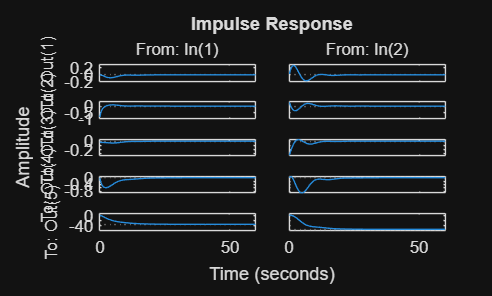


figure
impulse(Plat);

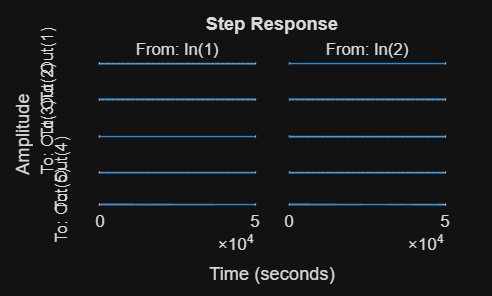


figure
step(Plat)



Plon = ss(A_lon,B_lon,C_lon,D_lon)


Plon =
 
  A = 
             x1        x2        x3        x4
   x1     -0.98   1.1e-15  -0.00065    -0.016
   x2         1         0         0         0
   x3      -2.2      -9.8    -0.033     0.074
   x4        77     -0.77     -0.23     -0.67
 
  B = 
         u1    u2
   x1  -2.4  0.29
   x2     0     0
   x3  0.18   9.8
   x4  -6.5     0
 
  C = 
             x1        x2        x3        x4
   y1         1         0         0         0
   y2         0       -80    -0.028         1
   y3         0  -1.4e-13         1     0.029
 
  D = 
       u1  u2
   y1   0   0
   y2   0   0
   y3   0   0
 
Continuous-time state-space model.


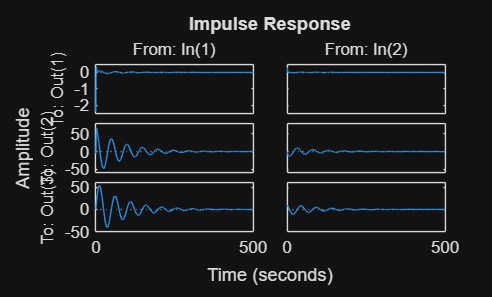


figure
impulse(Plon);

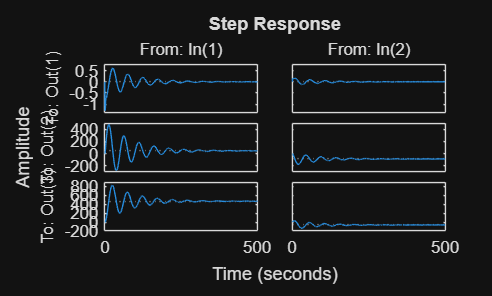


figure
step(Plon)